# DEMO_0015_FEA_ABAQUS_Twisted_Cylindrical_Gyroid

This is a demo for:

- Building a cylinder containing a radial Gyroid lattice structure

- Defining boundary conditions for finite element analysis

- Automatically generating an ABAQUS .inp file

- Triggering finite element analysis using ABAQUS

- Importing and visualising the results 

clear; close all; clc;

## Plot settings

cMap=jet(250);
faceAlpha1=1;
faceAlpha2=0.65;
edgeColor1='none';
edgeColor2='none';
fontSize=25; 
pColors=gjet(6);
markerSize=20;

## Control Parameters

% Path names
defaultFolder = fileparts(fileparts(mfilename('fullpath')));
savePath=fullfile(defaultFolder,'assets','temp');

% scriptPath = matlab.desktop.editor.getActiveFilename();
% scriptDir = fileparts(scriptPath); % Extract the directory path
% relativePath = fullfile('Simulations', 'Sim1');
% savePath = fullfile(scriptDir, relativePath);

% !!! These folders used to not exist
[status, msg, msgID] = mkdir(savePath);
if ~status
    warning('Failed to create directory: %s', msg);
end

% Defining file names
abaqusInpFileNamePart='twistedCylinder_FEA';
abaqusInpFileName=fullfile(savePath,[abaqusInpFileNamePart,'.inp']); %INP file name
abaqusDATFileName=fullfile(savePath,[abaqusInpFileNamePart,'.dat']); %DAT file nameme for exporting stress

% Define applied displacement & direction
displacementMagnitude = -0.2; %

% Material parameter set
E_youngs=5000;
v_poisson=0.33;

% Set parameters for individual gyroid
% NOTE: Not all geometry parameters yield a valid mesh. If the image resolution 
% is poor, or if the point spacing is too large, the mesh may be invalid. 

radiusInner = 0.3; 
radiusOuter = 1.2; 
height = 2; 
Dim=[radiusInner, radiusOuter, 2*pi, height]; % size vector
Ns=150; % number of sampling points
numPeriods=[2 12 2]; %Number of periods in each direction
levelset=0.5 ; %Isosurface level

pointSpacing=(radiusOuter-radiusInner)/40;
tolDir=pointSpacing/5; %Tolerance for detecting sides after remeshing

## Compute gyroid sample in cilyndrical arrangment

% Set parameters for individual gyroid
inputStruct.size= Dim; % characteristic length
inputStruct.Ns=Ns; % number of sampling points
inputStruct.isocap=1; %Option to cap the isosurface
inputStruct.surfaceCase='g'; %Surface type
inputStruct.numPeriods=numPeriods; %Number of periods in each direction
inputStruct.levelset=levelset ; %Isosurface level

## Evaluating cylindrical gyroid function

[~,~,~,S,X,Y,Z]=TPMS_LCS(inputStruct);

## Apply deformation matrix on grids

bendAngle = pi; %twist angle
a=linspace(0,bendAngle,size(Z,3));

Xp=X; Yp=Y; Zp=Z;
for q=1:1:size(Z,3)
    R = euler2DCM([0 0 a(q)]);
    x = X(:,:,q);
    y = Y(:,:,q);
    z = Z(:,:,q);
    v = [x(:) y(:) z(:)];
    %     vp = v*R;
    vp = (R*v')';

    xp = reshape(vp(:,1),size(x));
    yp = reshape(vp(:,2),size(x));
    zp = reshape(vp(:,3),size(x));

    Xp(:,:,q)=xp;
    Yp(:,:,q)=yp;
    Zp(:,:,q)=zp;
end

## Create new twisted grids

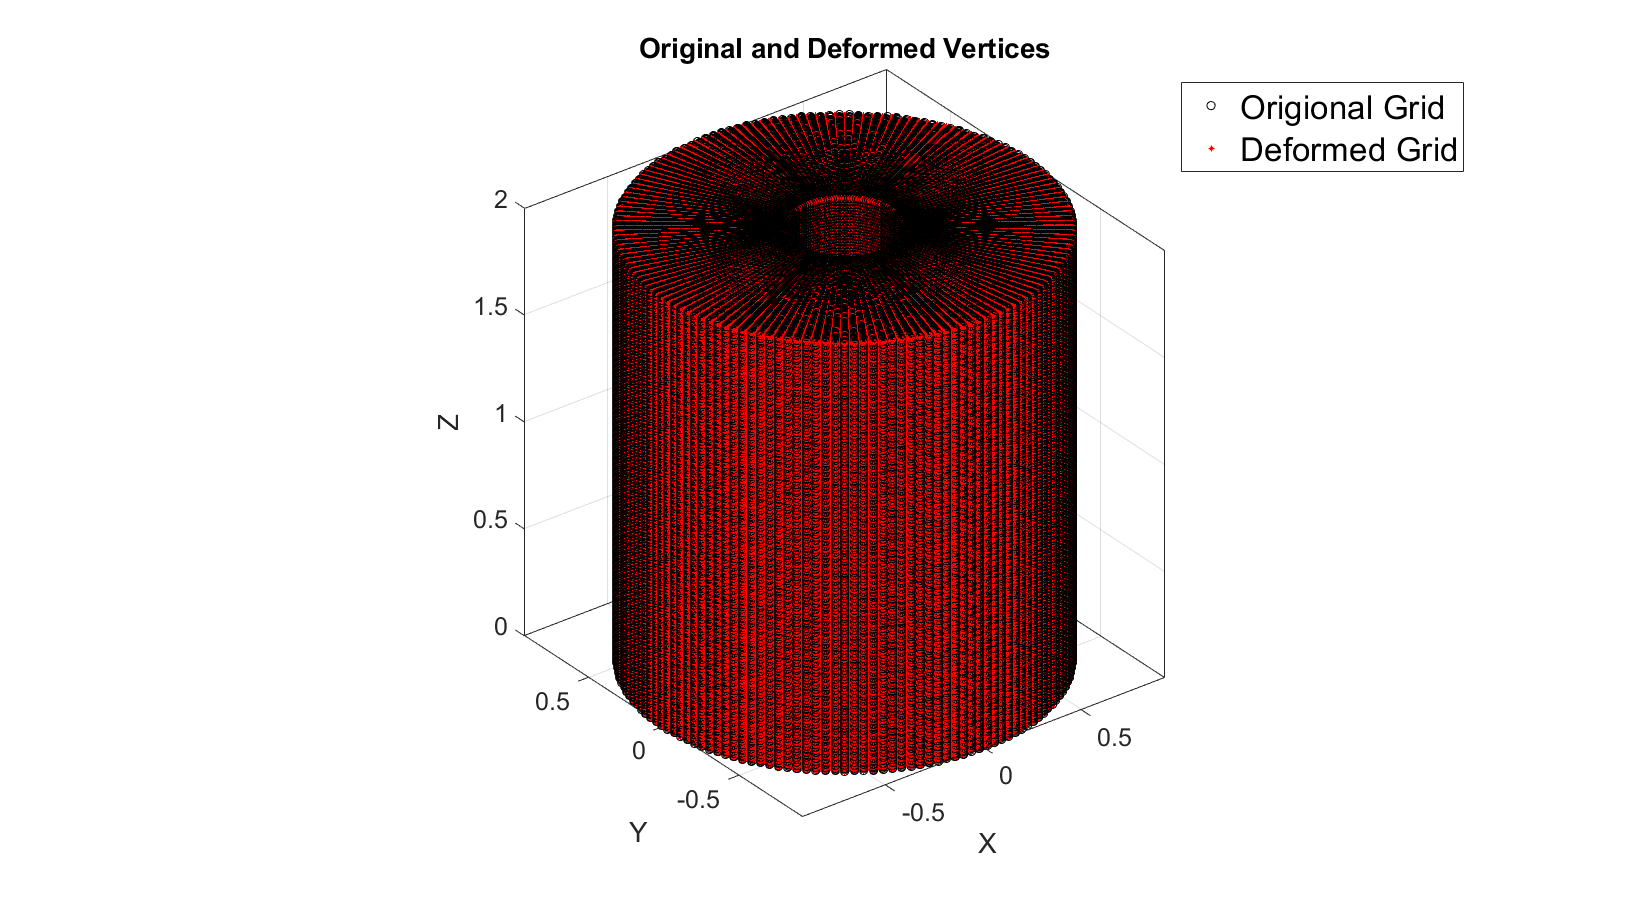

V=[X(:) Y(:) Z(:)];  %original grids
Vp=[Xp(:) Yp(:) Zp(:)]; %deformed grids

% Visualization
h1=cFigure; hold on; 
title ('Original and Deformed Vertices', 'FontSize',fontSize);
plotV(V,'ko','MarkerSize',5);
plotV(Vp,'r*','MarkerSize',3);
legend({'Origional Grid','Deformed Grid'}, 'FontSize',20);
axisGeom; 

drawnow;

## Construct iso-surface

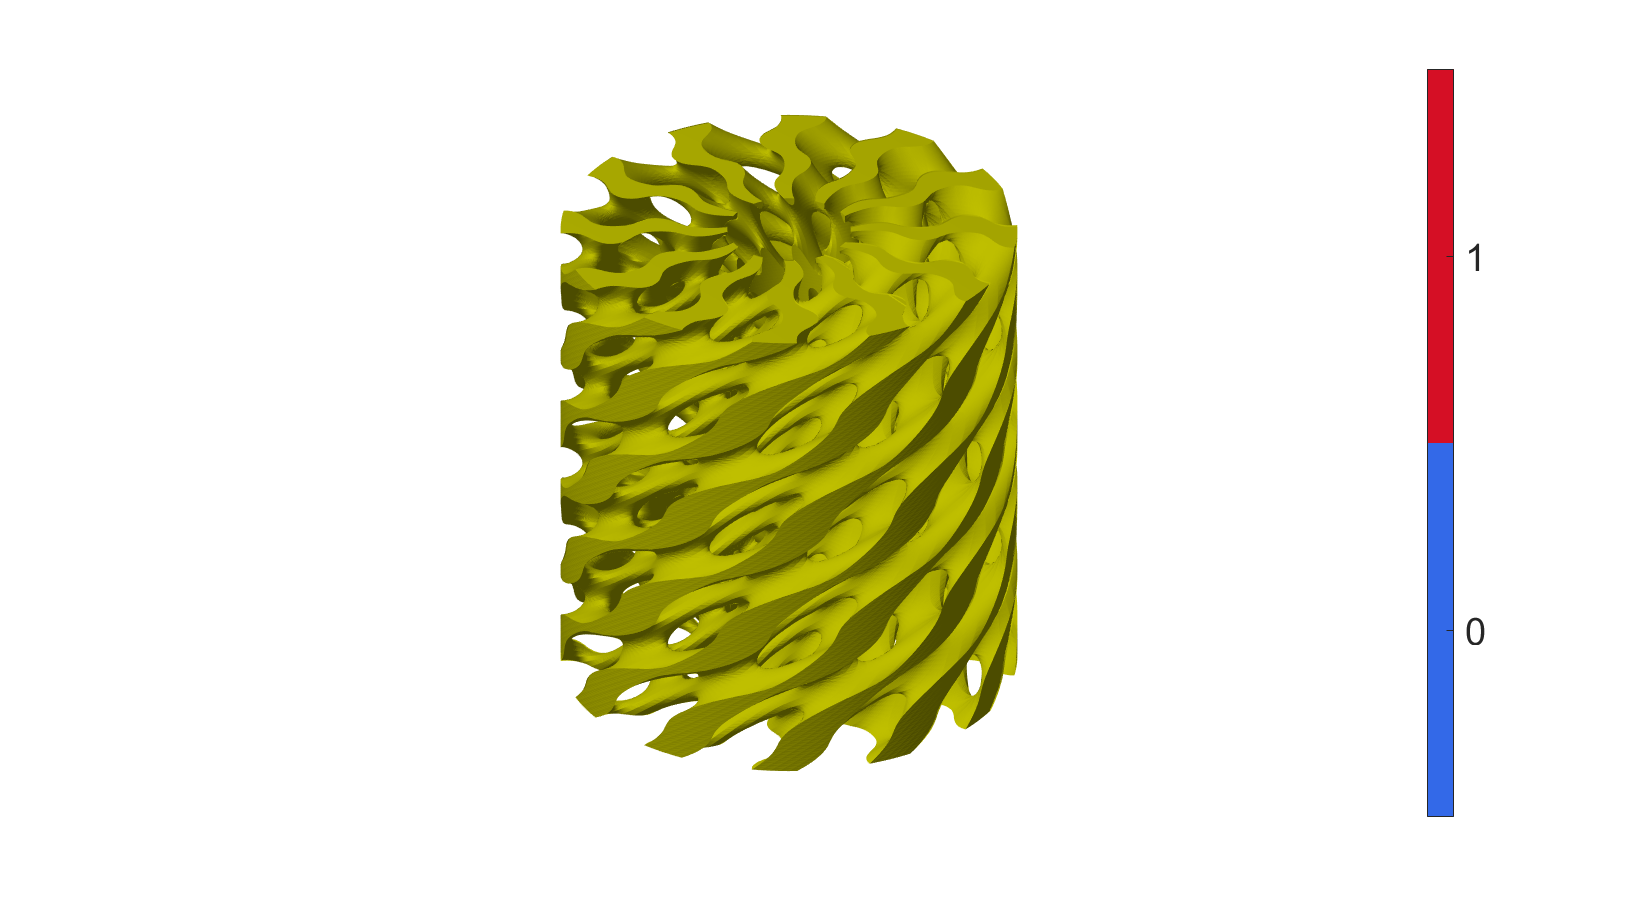

Sn=S;
[Fi,Vi] = isosurface(Xp,Yp,Zp,Sn,levelset);
[Fc,Vc] = isocaps(Xp,Yp,Zp,Sn,levelset);

[F,V] = joinElementSets({Fi,Fc},{Vi,Vc});
[F,V] = mergeVertices(F,V);
F=fliplr(F);

% Visualizing geometry
cFigure; hold on;
% title('GY-Scale-2','FontSize',fontSize);
gpatch(F,V,[0.75 0.75 0],'none', 1);
axisGeom(gca,fontSize); axis off;
colormap gjet; icolorbar; 
camlight left;

drawnow;

## Exporting STL file

% stlStruct.solidNames={'a'}; %names of parts
% stlStruct.solidFaces={F}; %Faces
% stlStruct.solidVertices={V}; %Vertices
% stlStruct.solidNormals={[]}; %Face normals (optional)
% 
% %Set main folder and fileName
% defaultFolder=fileparts(fileparts(mfilename('fullpath')));
% pathName=fullfile(defaultFolder, 'assets', 'STL');
% fileName=fullfile(pathName,'cylindrical_twisted_gyroid.stl');
% 
% export_STL_txt(fileName,stlStruct);

## Remesh using geomgram

pointSpacing=0.2; % changing this to see if meshes within 250k
optionStruct.pointSpacing=pointSpacing;
[F,V]=ggremesh(F,V,optionStruct);
C=zeros(size(F,1),1);

% Visualizing geometry
cFigure; hold on;
title('Geogram remeshed','FontSize',fontSize);
gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;
drawnow;

## Tetrahedral meshing using tetgen (see also `runTetGen`)

Create tetgen input structure

inputStruct.stringOpt='-pq1.2AaY';
% inputStruct.stringOpt='-pAaY'; % my edit
inputStruct.Faces=F;
inputStruct.Nodes=V;
inputStruct.holePoints=[];
inputStruct.faceBoundaryMarker=C; %Face boundary markers
inputStruct.regionPoints=getInnerPoint(F,V); %region points
inputStruct.regionA=1000000*tetVolMeanEst(F,V);
inputStruct.minRegionMarker=2; %Minimum region marker

% Mesh model using tetrahedral elements using tetGen
[meshOutput]=runTetGen(inputStruct); %Run tetGen

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 08-Feb-2025 13:25:30
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 08-Feb-2025 13:25:30
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 08-Feb-2025 13:25:31
--- Running TetGen to mesh input boundary--- 08-Feb-2025 13:25:31
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 


fprintf("%i Elements generated",size(meshOutput.elements,1))

49709 Elements generated


if size(meshOutput.elements,1) > 250000
    warning("more than 250k elements generated, job will fail")
end

% Access model element and patch data
Fb=meshOutput.facesBoundary;
Cb=meshOutput.boundaryMarker;
V=meshOutput.nodes;
CE=meshOutput.elementMaterialID;
E=meshOutput.elements;

## Visualizing mesh using `meshView`, see also `anim8`

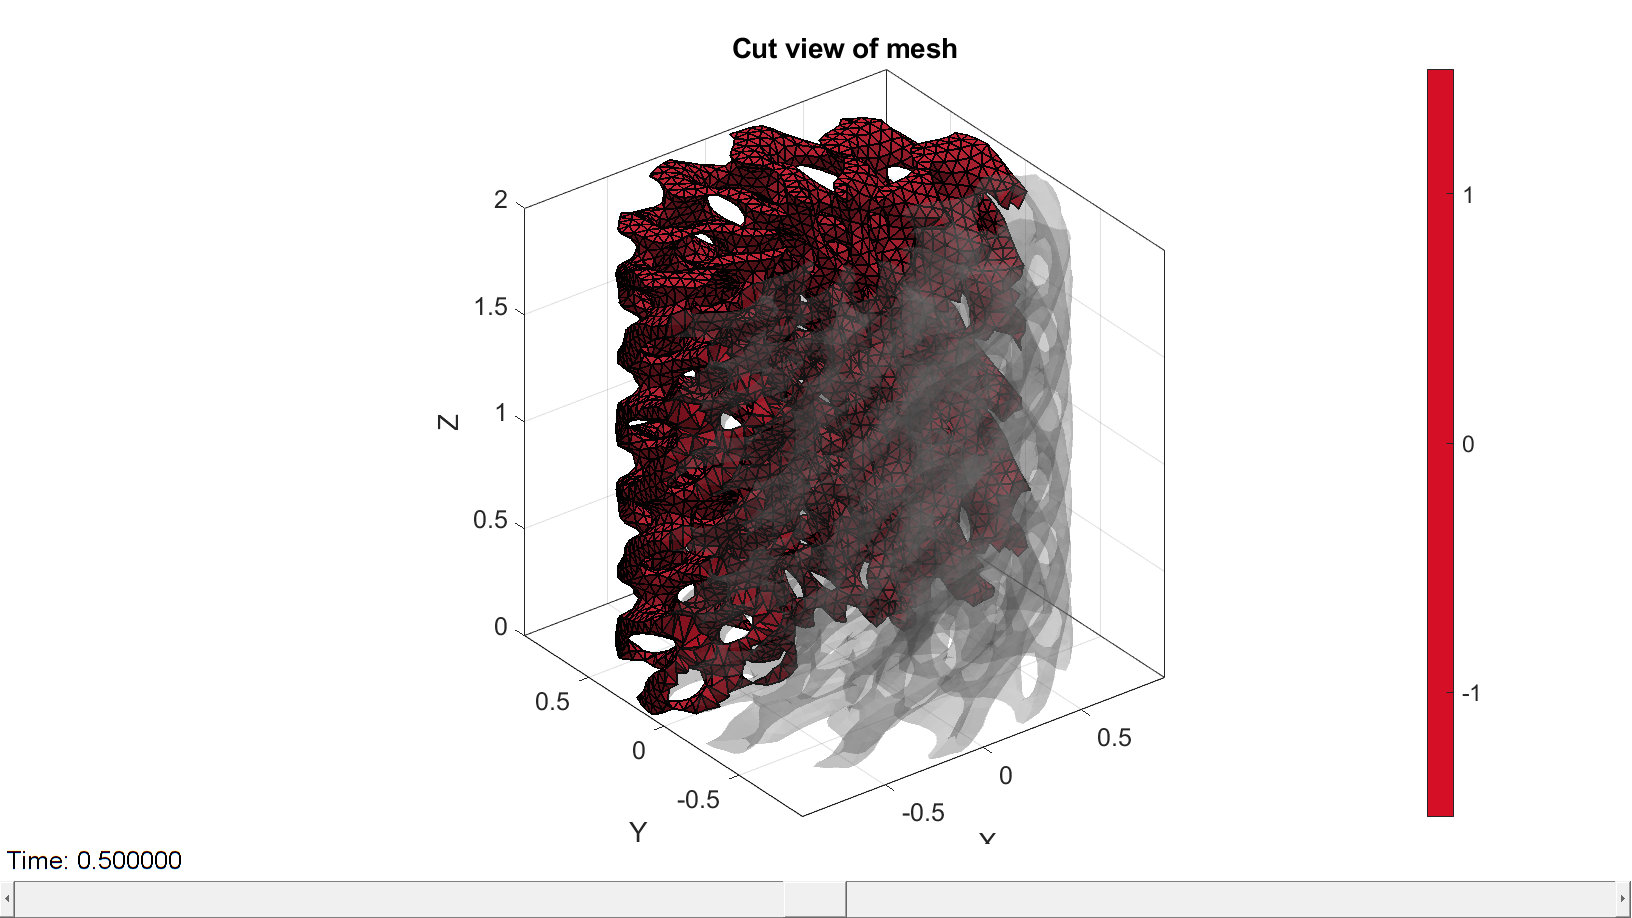

meshView(meshOutput);

## Defining node labels

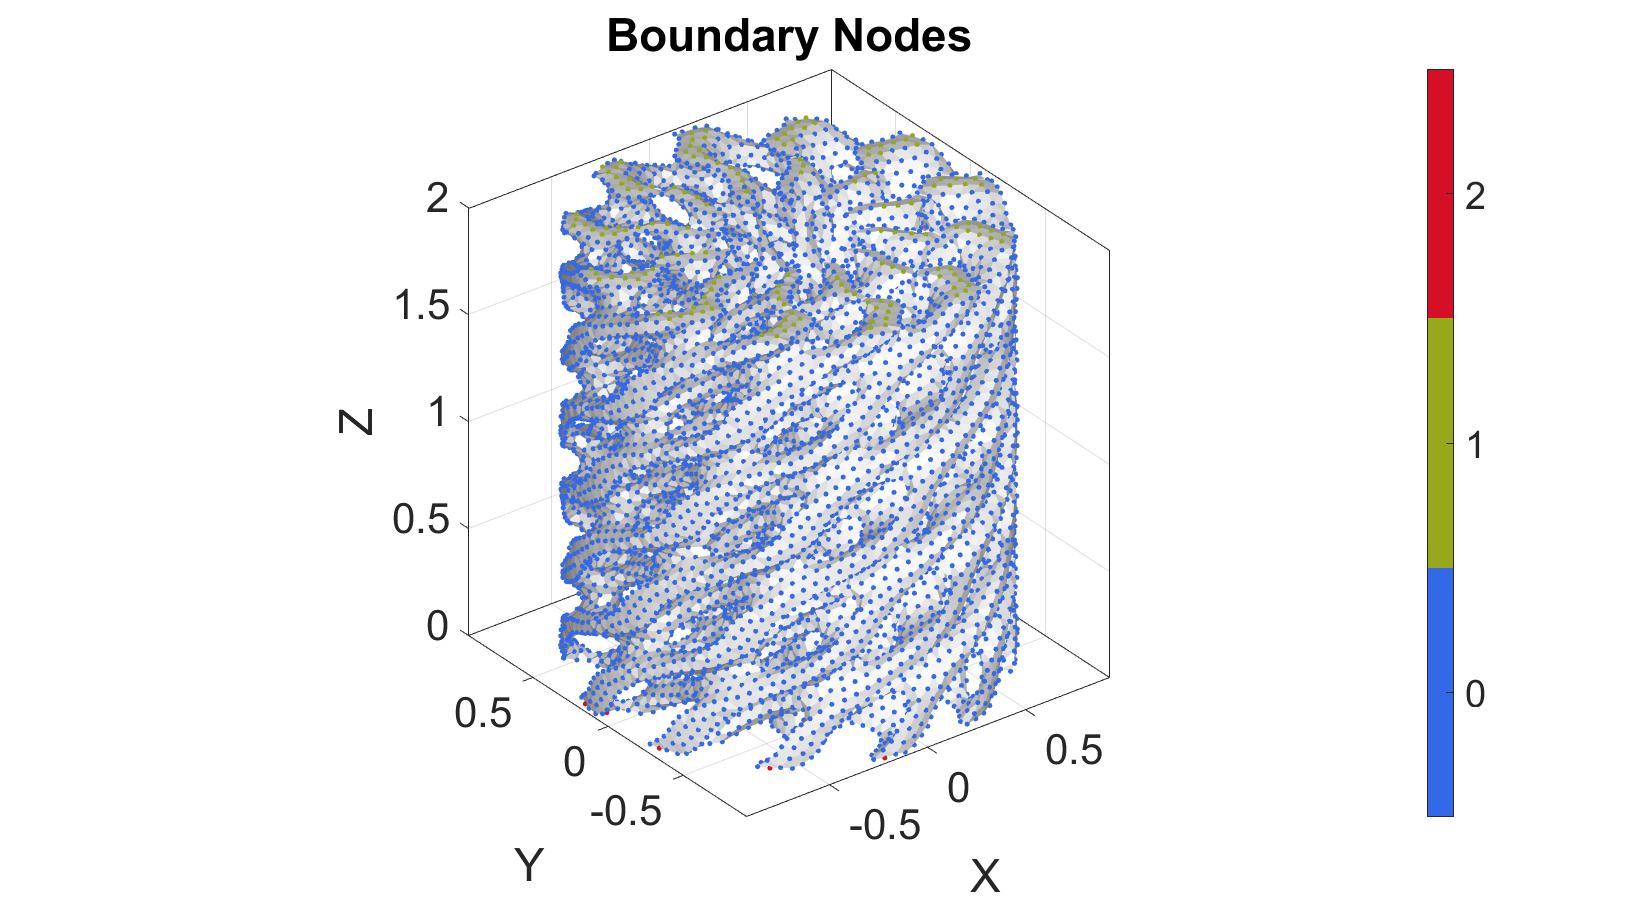

C_vertex=zeros(size(V,1),1);

logic1=V(:,3)>(Dim(1,4)-tolDir);
logic2=V(:,3)<tolDir;

C_vertex(logic1)=max(C_vertex(:))+1;
C_vertex(logic2)=max(C_vertex(:))+1;

% Visualizing vertex/node labels
hf=cFigure;
title('Boundary Nodes','FontSize',fontSize);
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; icolorbar;
camlight headlight;

drawnow;

## Defining the boundary conditions

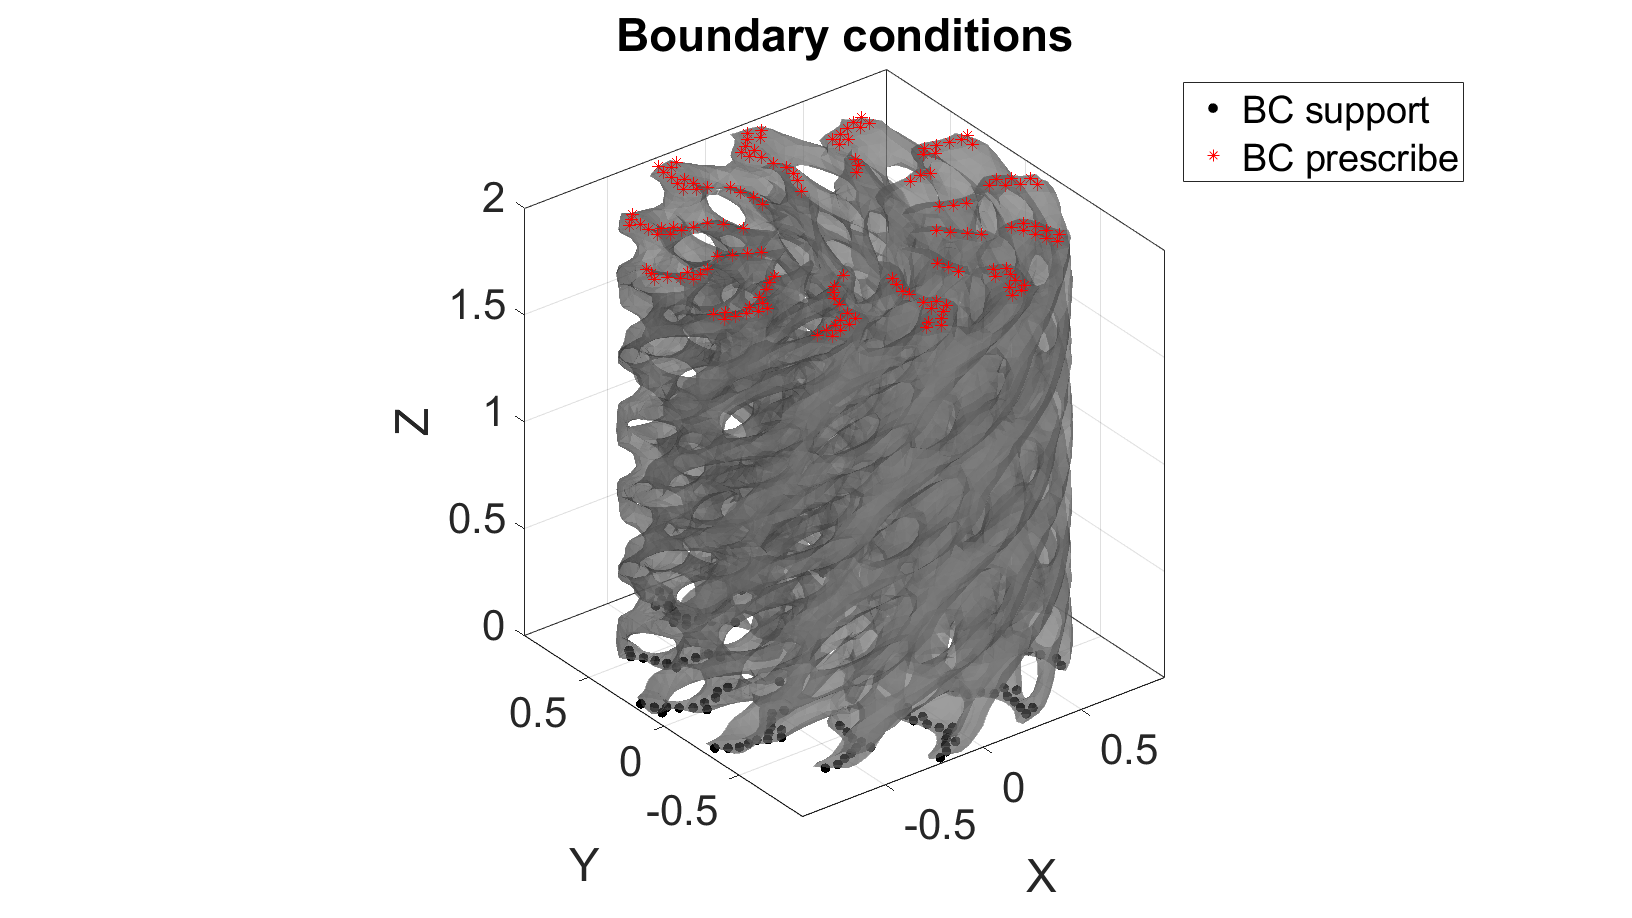

bcSupportList=find(C_vertex==2); %Bottom vertices
bcPrescribeList=find(C_vertex==1); %Top vertices

% Visualizing boundary conditions. 
% Markers plotted on the semi-transparent model denote the nodes in the
% various boundary condition lists.

hl=cFigure;
title('Boundary conditions','FontSize',fontSize);
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;
gpatch(Fb,V,'kw','none',0.5);

hl(1)=plotV(V(bcSupportList,:),'k.','MarkerSize',markerSize);
hl(2)=plotV(V(bcPrescribeList,:),'r*','MarkerSize',markerSize/3);
legend(hl,{'BC support','BC prescribe'});

axisGeom(gca,fontSize);
camlight headlight;

drawnow;

## Defining the abaqus input structure

See also `abaqusStructTemplate` and `abaqusStruct2inp` and the abaqus user manual.

%%--> Heading
abaqus_spec.Heading.COMMENT{1}='Job name: ABAQUS inp file creation demo';
abaqus_spec.Heading.COMMENT{2}='Generated by: GIBBON';

%%--> Preprint
abaqus_spec.Preprint.ATTR.echo='NO';
abaqus_spec.Preprint.ATTR.model='NO';
abaqus_spec.Preprint.ATTR.history='NO';
abaqus_spec.Preprint.ATTR.contact='NO';
abaqus_spec.Preprint.ATTR.contact='NO';

%--> Part

% Node
nodeIds=(1:1:size(V,1))';
abaqus_spec.Part.COMMENT='This section defines the part geometry in terms of nodes and elements';
abaqus_spec.Part.ATTR.name='Cylinder';
abaqus_spec.Part.Node={nodeIds,V};

% Element
elementIds=(1:1:size(E,1));
abaqus_spec.Part.Element{1}.ATTR.type='C3D4';%'C3D8R';
abaqus_spec.Part.Element{1}.VAL={elementIds(:),E};

% Element sets
abaqus_spec.Part.Elset{1}.ATTR.elset='Set-1';
abaqus_spec.Part.Elset{1}.VAL=elementIds;

% Sections
abaqus_spec.Part.Solid_section.ATTR.elset='Set-1';
abaqus_spec.Part.Solid_section.ATTR.material='Elastic';

%%--> Assembly
abaqus_spec.Assembly.ATTR.name='Assembly-1';
abaqus_spec.Assembly.Instance.ATTR.name='Cylinder-assembly';
abaqus_spec.Assembly.Instance.ATTR.part='Cylinder';

abaqus_spec.Assembly.Nset{1}.ATTR.nset='Set-1';
abaqus_spec.Assembly.Nset{1}.ATTR.instance='Cylinder-assembly';
abaqus_spec.Assembly.Nset{1}.VAL=bcSupportList(:)';

abaqus_spec.Assembly.Nset{2}.ATTR.nset='Set-2';
abaqus_spec.Assembly.Nset{2}.ATTR.instance='Cylinder-assembly';
abaqus_spec.Assembly.Nset{2}.VAL=bcPrescribeList(:)';

abaqus_spec.Assembly.Nset{3}.ATTR.nset='all';
abaqus_spec.Assembly.Nset{3}.ATTR.instance='Cylinder-assembly';
abaqus_spec.Assembly.Nset{3}.VAL=1:1:size(V,1);

%%--> Material
abaqus_spec.Material.ATTR.name='Elastic';
abaqus_spec.Material.Elastic=[E_youngs v_poisson];

%%--> Step
abaqus_spec.Step.ATTR.name='Step-1';
abaqus_spec.Step.ATTR.nlgeom='YES';
abaqus_spec.Step.Static=[0.01 1 1e-5 0.1];

%--> Boundary
abaqus_spec.Step.Boundary{1}.VAL={'Set-1', 'ENCASTRE'};
abaqus_spec.Step.Boundary{2}.VAL={'Set-2',[3,3],displacementMagnitude};

%--> Output
%Nodal coordinates
abaqus_spec.Step.Node_print{1}.ATTR.nset='all';
abaqus_spec.Step.Node_print{1}.ATTR.frequency = 1;
abaqus_spec.Step.Node_print{1}.VAL='COORD';

abaqus_spec.Step.El_print{1}.VAL='S';
abaqus_spec.Step.El_print{2}.VAL='E';

## writing INP file

abaqusStruct2inp(abaqus_spec,abaqusInpFileName);

## Run the job using Abaqus

lockFileName=fullfile(savePath,[abaqusInpFileNamePart,'.lck']);
if exist(lockFileName,'file')
    warning('Lockfile found and deleted')
    delete(lockFileName);
end

oldPath=pwd; %Get current working directory
cd(savePath); %Set new working directory to match save patch

abaqusPath='C:\SIMULIA\Commands\abaqus.bat';%'/usr/bin/abaqus'; %Abaqus excute command or path
[runFlag, cmdOut] = system([abaqusPath,' inp=',abaqusInpFileName,' job=',abaqusInpFileNamePart,' interactive ask_delete=OFF', 'cpus=',int2str(6)]);
disp(cmdOut);

cd(oldPath); %Restore working directory

## Import and visualize abaqus results

Importing the abaqus .dat file 

% [abaqusData]=importAbaqusDat(abaqusDATFileName);

try
    % Attempt to import the Abaqus data file.
    abaqusData = importAbaqusDat(abaqusDATFileName);
catch ME
    % If import fails, open the file for reading.
    fid = fopen(abaqusDATFileName, 'rt');
    if fid == -1
        error('Unable to open file: %s', abaqusDATFileName);
    else
        fileText = fread(fid, '*char')';
        fclose(fid);
        % Check if the error message appears in the file.
        if contains(fileText, '***ERROR: Academic Teaching license is limited to 250000 nodes.')
            warning('The file %s indicates an Academic Teaching license limitation.', abaqusDATFileName);
            % Optionally, you might set abaqusData to a default value here.
        else
            % If the error message isn’t present, rethrow the original error.
            rethrow(ME);
        end
    end
end

## Get element data

E_effectiveStress=zeros(size(E,1),numel(abaqusData.STEP.INCREMENT)+1);
E_effectiveStrain=zeros(size(E,1),numel(abaqusData.STEP.INCREMENT)+1);
for q=1:1:numel(abaqusData.STEP.INCREMENT)
    
    for d=1:1:2        
        dataSet=abaqusData.STEP.INCREMENT(q).elementOutput(d); %Get data structure
        switch d
            case 1
                % Get element data across all 1 integration points
                D11_PT=reshape(dataSet.data.S11,1,size(E,1))';
                D22_PT=reshape(dataSet.data.S22,1,size(E,1))';
                D33_PT=reshape(dataSet.data.S33,1,size(E,1))';
                D12_PT=reshape(dataSet.data.S12,1,size(E,1))';
                D13_PT=reshape(dataSet.data.S13,1,size(E,1))';
                D23_PT=reshape(dataSet.data.S23,1,size(E,1))';
            case 2
                % Get element data across all 1 integration points
                D11_PT=reshape(dataSet.data.E11,1,size(E,1))';
                D22_PT=reshape(dataSet.data.E22,1,size(E,1))';
                D33_PT=reshape(dataSet.data.E33,1,size(E,1))';
                D12_PT=reshape(dataSet.data.E12,1,size(E,1))';
                D13_PT=reshape(dataSet.data.E13,1,size(E,1))';
                D23_PT=reshape(dataSet.data.E23,1,size(E,1))';                
        end
        
        % Get mean element metrics
        D11=mean(D11_PT,2);
        D22=mean(D22_PT,2);
        D33=mean(D33_PT,2);
        D12=mean(D12_PT,2);
        D13=mean(D13_PT,2);
        D23=mean(D23_PT,2);
        
        % Calculate effective (Von Mises) metrics
        switch d
            case 1
                E_effectiveStress(:,q+1)=(1/sqrt(2)).*sqrt((D11-D22).^2+(D11-D33).^2+(D33-D11).^2+6*D12.^2+6*D23.^2+6*D13.^2);
            case 2
                E_effectiveStrain(:,q+1)=(1/sqrt(2)).*sqrt((D11-D22).^2+(D11-D33).^2+(D33-D11).^2+6*D12.^2+6*D23.^2+6*D13.^2);
        end
    end
end

Plotting the simulated results using `anim8` to visualize and animate deformations

%Getting final nodal coordinates
V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR3];
U=V_def-V; %Displacements

colorDataVertices=sqrt(sum(U.^2,2)); %Displacement magnitude data for coloring 

timeVec=[0 abaqusData.STEP(1).INCREMENT(:).TOTAL_TIME_COMPLETED];

% Get limits for plotting
minV=min([V;V_def],[],1); %Minima
maxV=max([V;V_def],[],1); %Maxima

% Create basic view and store graphics handle to initiate animation
hf=cFigure; %Open figure
gtitle([abaqusInpFileNamePart,': Displacement data. Press play to animate']);
hp=gpatch(Fb,V_def,colorDataVertices,'none',1); %Add graphics object to animate
gpatch(Fb,V,0.5*ones(1,3),'k',0.25); %A static graphics object
axisGeom(gca,fontSize);
colormap(gjet(250)); colorbar;
caxis([0 max(colorDataVertices)]);
axis([minV(1) maxV(1) minV(2) maxV(2) minV(3) maxV(3)]); %Set axis limits statically
view(130,25); %Set view direction
camlight headlight;

% Set up animation features
animStruct.Time=timeVec; %The time vector
for qt=1:1:numel(timeVec) %Loop over time increments    
    if qt>1
        V_def=[abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR1...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR2...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR3];
    else
        V_def=V;
    end    
    U=V_def-V; %Displacements
    colorDataVertices=sqrt(sum(U(:,3).^2,2)); %New color data
   
    %Set entries in animation structure
    animStruct.Handles{qt}=[hp hp]; %Handles of objects to animate
    animStruct.Props{qt}={'Vertices','CData'}; %Properties of objects to animate
    animStruct.Set{qt}={V_def,colorDataVertices}; %Property values for to set in order to animate
end
anim8(hf,animStruct); %Initiate animation feature
drawnow;

Plotting the simulated results using `anim8` to visualize and animate deformations

%Getting final nodal coordinates
V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR3];
U=V_def-V; %Displacements

[FE,C_FE_effectiveStress]=element2patch(E,E_effectiveStress(:,end),'tet4');
[indBoundary]=tesBoundary(FE,V);
FEb=FE(indBoundary,:);
colorDataFaces=C_FE_effectiveStress(indBoundary); 

timeVec=[0 abaqusData.STEP(1).INCREMENT(:).TOTAL_TIME_COMPLETED];

% Get limits for plotting
minV=min([V;V_def],[],1); %Minima
maxV=max([V;V_def],[],1); %Maxima

% Create basic view and store graphics handle to initiate animation
hf=cFigure; %Open figure
gtitle([abaqusInpFileNamePart,': Effective stress data. Press play to animate']);
hp=gpatch(FEb,V_def,colorDataFaces,'none',1); %Add graphics object to animate
gpatch(FEb,V,0.5*ones(1,3),'k',0.25); %A static graphics object
axisGeom(gca,fontSize);
colormap(gjet(250)); colorbar;
caxis([0 max(E_effectiveStress(:))]);
axis([minV(1) maxV(1) minV(2) maxV(2) minV(3) maxV(3)]); %Set axis limits statically
view(130,25); %Set view direction
camlight headlight;

% Set up animation features
animStruct.Time=timeVec; %The time vector
for qt=1:1:numel(timeVec) %Loop over time increments    
    if qt>1
        V_def=[abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR1...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR2...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR3];
    else
        V_def=V;
    end    
    U=V_def-V; %Displacements
    
    [~,C_FE_effectiveStress]=element2patch(E,E_effectiveStress(:,qt),'tet4');
    colorDataFaces=C_FE_effectiveStress(indBoundary); %New color data
   
    %Set entries in animation structure
    animStruct.Handles{qt}=[hp hp]; %Handles of objects to animate
    animStruct.Props{qt}={'Vertices','CData'}; %Properties of objects to animate
    animStruct.Set{qt}={V_def,colorDataFaces}; %Property values for to set in order to animate
end
anim8(hf,animStruct); %Initiate animation feature
drawnow;

***LatticeWorks footer text*** 

License: [https://github.com/mahtab-vafaee/LatticeWorks/blob/main/LICENSE](https://github.com/mahtab-vafaee/LatticeWorks/blob/main/LICENSE)

Copyright (C) 2023 Mahtab Vafaeefar and the LatticeWorks contributors